# **DC Motor simulation**

## **Modeling**

### Circulart plate & bar inertia

${J_{\mathrm{bar}} \;=\;m}_{\mathrm{bar}} \left({L_{\mathrm{bar}} }^2 +\frac{1}{4}{H_{\mathrm{bar}} }^2 \right)$, $J_{\mathrm{cir}} =\;\frac{1}{2}m_{\mathrm{cir}} {R_{\mathrm{cir}} }^2 +m_{\mathrm{cir}} L_{\mathrm{cir}}$


$$J_{\mathrm{Load}} =J_{\mathrm{bar}} +J_{\mathrm{cir}}$$


### Load Torque


$$T-\left(\frac{1}{\alpha }{\left(\frac{N_1 }{N_2 }\right)}^2 J_{\mathrm{Load}} \overset{\cdot \cdot }{\theta_M } +\frac{1}{\alpha }{\left(\frac{N_1 }{N_2 }\right)}^2 B_{\mathrm{Load}} \overset{\cdot }{\theta_M } \right)=J_{\mathrm{eq}} \overset{\cdot \cdot }{\theta_M } +B_{\mathrm{eq}} \overset{\cdot }{\theta_M }$$


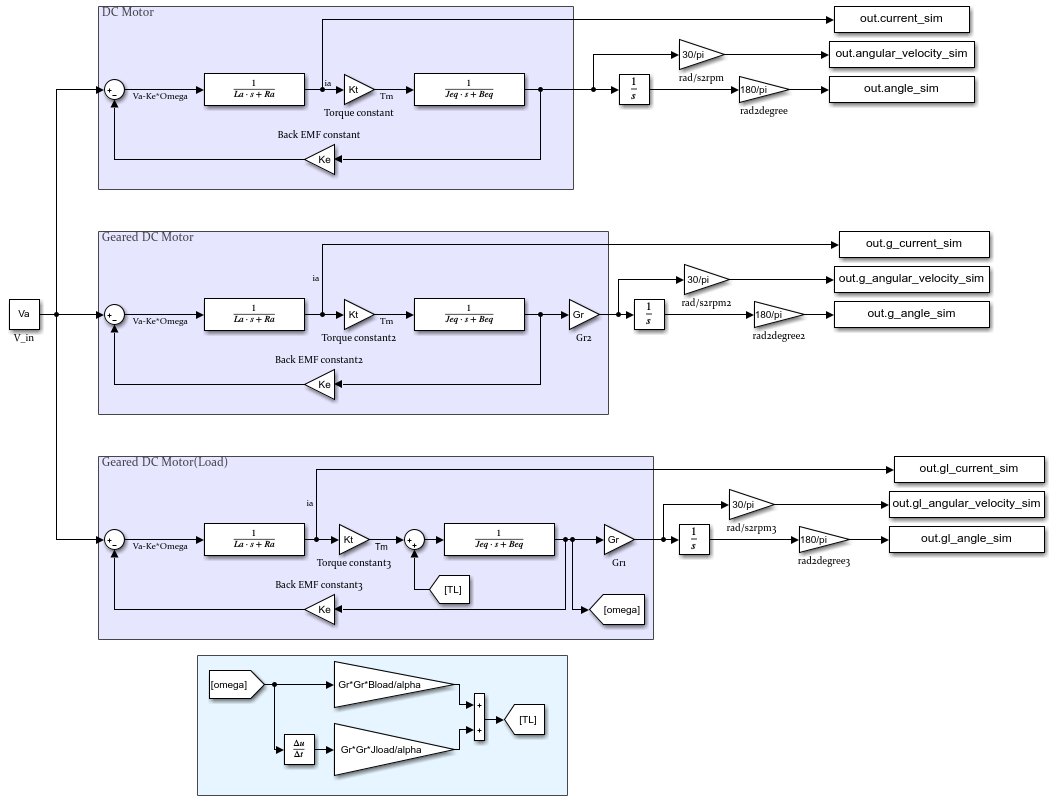

clc; clear;

## Motor Parameter

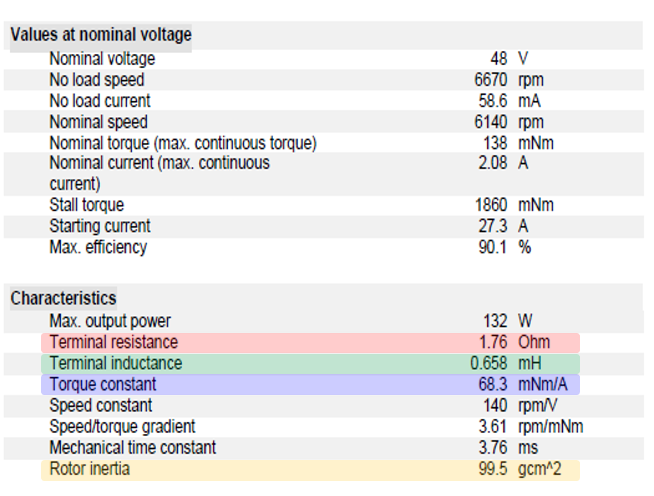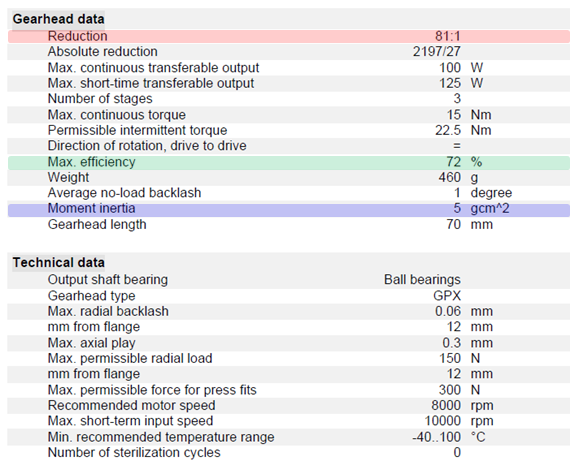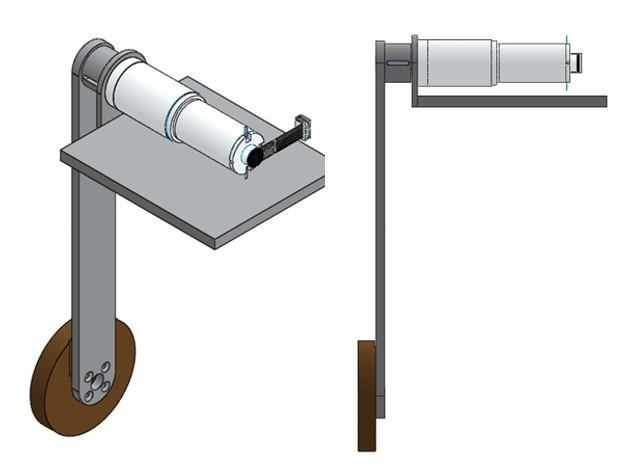

Va = 48;                    % Input Voltage [V]
Ra = 1.76;                  % Resistance [Ohm]
La = 0.658e-3;              % Inductance [H]
Kt = 68.3e-3;               % Torque Constant [Nm/A]
Ke = Kt;                    % EMF Constnat(Counter Electromotive Force) [Nm/A]
 J = 99.5e-7;               % Rotor inertia [kg^2]
 t = 3.76e-3;               % Mechanical Time Constant [s]
 b = J/t;                   % Friction coefficient [Nm/(rad/s)] 
D2R = 180/pi;

## Gear Parameter

alpha = 0.72;                           % Gear Max Efficiency
   Gr = 1/81;                           % Gear Ratio
Jgear = 5e-7;                           % Gear Intertia [Kgm^2]
  Jeq = J + (1/alpha)*Gr*Gr*Jgear;      % Motor + Gear Inertia [kgm^2]                                
  Beq = b;                              % Motor + Gear Friction Coefficient [Nm/(rad/s)]

## Bar & Circular Parameter

bar_m = 0.175;                                         % bar mass [kg]
bar_l = 0.3;                                           % bar lengh [m]
bar_h = 0.025;                                         % bar height [m]

cir_m = 0.34;                                          % circular mass [kg]
cir_l = 0.3;                                           % circular length [m] 
cir_r = 0.05;                                          % circular radius [m]

 Jbar = (1/3)*bar_m*(bar_l^2 + (1/4)*bar_h^2);         % bar Inertia [kgm^2]
 Jcir = (1/2)*(cir_m*cir_r^2) + cir_m*(cir_l^2);       % circular Inertia [kgm^2]
Jload = Jbar + Jcir;                                   % bar&circular Inertia [kgm^2]
Bload = Jload/t;                                       % bar&circular Friction Coeffieicnt [Nm/(rad/s)]

## **Graph(48V, DC, Geared DC& Angle, Angular Velocity, Current)**

simout = sim('hw2');
figure('Units', 'pixels', 'pos', [100 100 1800 400]);

### Angle

subplot(1,3,1);
plot(simout.angle_sim.time, simout.angle_sim.signals.values, '-*', 'LineWidth', 2);
hold on;
plot(simout.g_angular_velocity_sim.time, simout.g_angular_velocity_sim.signals.values, 'LineWidth', 2);

xlabel('t [s]', 'fontsize', 10);
ylabel('velocity [rad/s]', 'fontsize', 10);
legend('angular velocity', 'geared angular velocity');
title('Angular Velocity', 'fontsize', 20);
grid on;

### **Angular Velocity **

subplot(1,3,2);     
plot(simout.angular_velocity_sim.time, simout.angular_velocity_sim.signals.values, '-*', 'LineWidth', 2);
hold on;
plot(simout.g_angular_velocity_sim.time, simout.g_angular_velocity_sim.signals.values, 'LineWidth', 2);

xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('angle', 'geared angle');
title('Angle', 'fontsize', 20);
grid on;

### Current

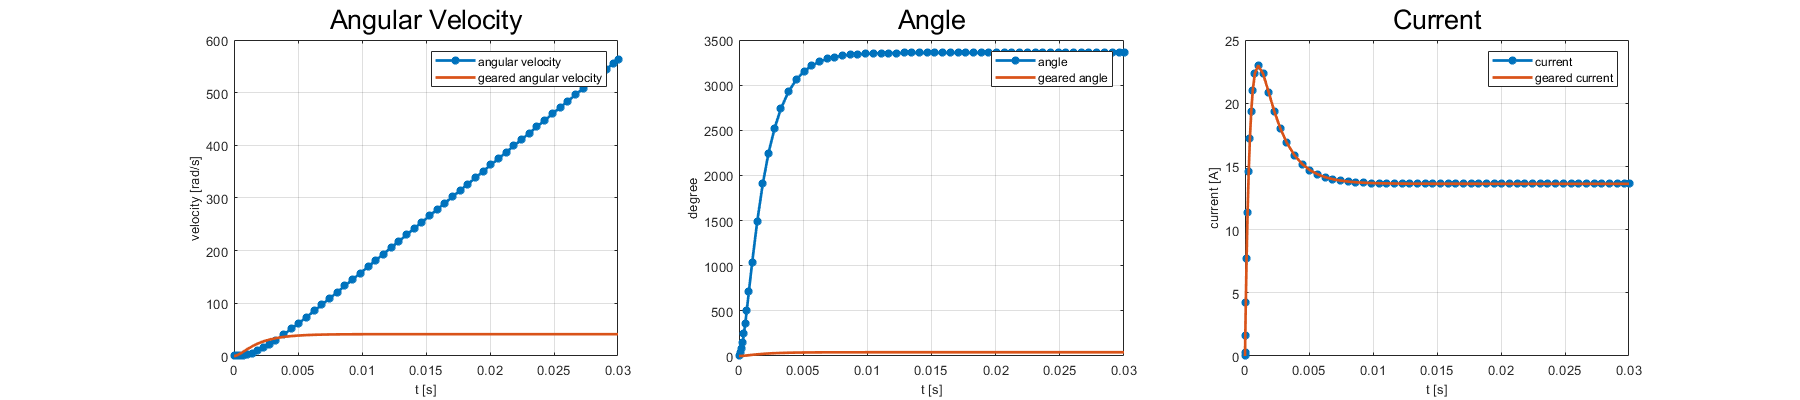

subplot(1,3,3);
plot(simout.current_sim.time, simout.current_sim.signals.values, '-*', 'LineWidth', 2);
hold on;
plot(simout.g_current_sim.time, simout.g_current_sim.signals.values, 'LineWidth', 2);

xlabel('t [s]', 'fontsize', 10);
ylabel('current [A]', 'fontsize', 10);
legend('current', 'geared current');
title('Current', 'fontsize', 20);
grid on;

## **Graph(48V Geared DC Load & Angle, Angular Velocity, Current)**

simout = sim('hw2');
figure('Units', 'pixels', 'pos', [100 100 1800 400]);

### Angle

subplot(1,3,1);
plot(simout.gl_angle_sim.time, simout.gl_angle_sim.signals.values, 'LineWidth', 2);

xlabel('t [s]', 'fontsize', 10);
ylabel('degree', 'fontsize', 10);
legend('angular velocity');
title('Angle', 'fontsize', 20);
grid on;

### **Angular Velocity **

subplot(1,3,2);     
plot(simout.gl_angular_velocity_sim.time, simout.gl_angular_velocity_sim.signals.values, 'LineWidth', 2);

xlabel('t [s]', 'fontsize', 10);
ylabel('velocity [rad/s]', 'fontsize', 10);
legend('angle');
title('Angular Velocity', 'fontsize', 20);
grid on;

### Current

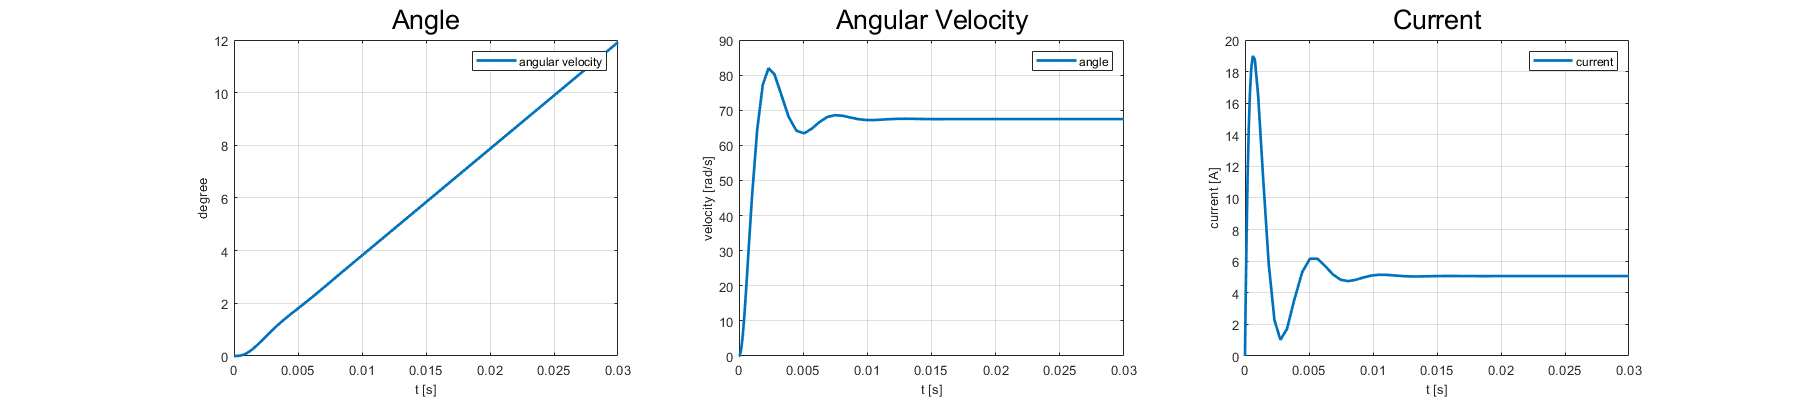

subplot(1,3,3);
plot(simout.gl_current_sim.time, simout.gl_current_sim.signals.values, 'LineWidth', 2);

xlabel('t [s]', 'fontsize', 10);
ylabel('current [A]', 'fontsize', 10);
legend('current');
title('Current', 'fontsize', 20);
grid on;